clear
warning off
data = readtable("../output/filtered_siderophores_BGC.csv");
siderophore_BGC_info = table2cell(data);

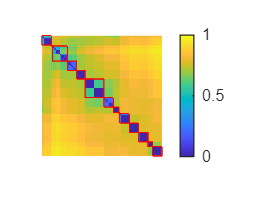

load ../input/distm4.mat %siderophore synthetic gene distance
tree = linkage(distm_syn,'average');
leafOrder = optimalleaforder(tree,distm_syn);
dist_thresh = 0.6;
[metallore_groupid,metallore_groupnum,changedleaforder_bygroups] = Cluster_byconnection(distm_syn,dist_thresh,leafOrder);
distm_reorder = distm_syn(changedleaforder_bygroups,changedleaforder_bygroups);
metallore_groupid = metallore_groupid(changedleaforder_bygroups);
plot_cluster(distm_reorder,metallore_groupid)

siderophore_BGC_info_reorder = siderophore_BGC_info(changedleaforder_bygroups,:);
for i =1:length(metallore_groupid)
    siderophore_BGC_info_reorder{i,11} = metallore_groupid(i);
end

gbk_data = readtable("../input/siderophore_BGC_all_domain_info.csv");
fileContent = fileread("../input/unique_aSDomain.txt");
lines = splitlines(fileContent);
unique_asDomain = cellstr(lines);
%把csv文件变成struc文件
unique_ids = unique(gbk_data.id);
gbk_struct = struct('id', {}, 'aSDomain', {}, 'domain_translation', {},'gene_translation', {},'gene_name', {},'locus_tag', {});
for i = 1:length(unique_ids)
    current_id = unique_ids{i};
    idx = strcmp(gbk_data.id, current_id);
    aSDomain_list = gbk_data.aSDomain(idx);
    translation_list = gbk_data.gene_translation(idx);
    gbk_struct(i).id = current_id;
    gbk_struct(i).aSDomain = aSDomain_list;
    gbk_struct(i).translation = translation_list;
end

[~, loc] = ismember({gbk_struct.id},data.dataname);

distm_BGC_101 = distm_syn(loc,loc);
gbk_struct = gbk_struct';
%save ../output/gbk_struct.mat gbk_struct

is_gene = false(1, length(gbk_struct));
result = table();
for k = 1:(length(unique_asDomain)-1)
    current_domain = unique_asDomain{k};
    
    translations = cell(1, length(gbk_struct));
    is_gene = false(1, length(gbk_struct));
    for i = 1:length(gbk_struct)
       
        idx = find(strcmp(gbk_struct(i).aSDomain, current_domain));
        if ~isempty(idx)
            is_gene(i) = true;
            translations{i} = gbk_struct(i).translation{idx(1)};
        else
            
            is_gene(i) = false;
        end     

    end

    
    translations(~is_gene) = [];
    if sum(is_gene)<2
        correlation = 0.5;
        num_genes = 1;
        metallore_groupnum=1;
        num_sider_group_2 = 0;
        num_sider_group_4 = 0;
    else

        
        distm_gene = zeros(sum(is_gene), sum(is_gene));

        
        for i = 1:length(translations)
            for j = i:length(translations)
               
                distm_gene(i, j) = seqpdist({translations{i}, translations{j}}, 'Method', 'p-distance', 'PairwiseAlignment', true);
                distm_gene(j, i) = distm_gene(i, j); % 对称矩阵
            end
        end

        distm_syn_subset = distm_BGC_101(is_gene, is_gene);
        tree = linkage(distm_syn_subset,'average');
        leafOrder = optimalleaforder(tree,distm_syn_subset);
        dist_thresh=0.4;
        [metallore_groupid,metallore_groupnum,changedleaforder_bygroups] = Cluster_byconnection(distm_syn_subset,dist_thresh,leafOrder);
        groupnum=max(metallore_groupid);
        groupsize = zeros(1, groupnum);
        for g=1:groupnum
            groupsize(g)=sum(metallore_groupid==g);
        end
        num_sider_group_2 = find(groupsize > 2);
        num_sider_group_4 = find(groupsize > 4);
        
        correlation = corr(distm_gene(:), distm_syn_subset(:));

        num_genes = sum(is_gene);
    end
   
    result_temp = table(string(current_domain), correlation, num_genes,metallore_groupnum,length(num_sider_group_2), length(num_sider_group_4),...
        'VariableNames', {'aSDomain', 'correlation', 'num_genes','num_siderophore_group','num_siderophore_group_filter_2','num_siderophore_group_filter_4'});

    result = [result; result_temp];

end

writetable(result,"../output/128_resulte_of_correlation_and_counts_one2many.csv")


%plot PBP2 distance heatmap
domain_name = 'Peripla_BP_2';
translations = cell(1, length(gbk_struct));
is_gene = false(1, length(gbk_struct));
for i = 1:length(gbk_struct)
        
        idx = find(strcmp(gbk_struct(i).aSDomain, domain_name));
        if ~isempty(idx)
            is_gene(i) = true;
            translations{i} = gbk_struct(i).translation{idx(1)};
        else
            
            is_gene(i) = false;
        end
end
all_id = {gbk_struct.id};
PBP2_id = all_id(is_gene);
PBP2_seqs = translations(is_gene);
distm_rec = zeros(length(PBP2_seqs),length(PBP2_seqs));
for i = 1:length(PBP2_seqs)
    distm_rec(i,i)=0;
    for j = i+1:length(PBP2_seqs)
        seq1 = PBP2_seqs{i};
        seq2 = PBP2_seqs{j};        
        dist = seqpdist({seq1,seq2},'PairwiseAlignment', true,'Method','p-dist');
        distm_rec(i,j) = dist;
        distm_rec(j,i) = dist;
    end
end
sidero_all_id = siderophore_BGC_info(:,1);
sidero_product = siderophore_BGC_info(:,6);

[isMatch, idxInSidero] = ismember(PBP2_id, sidero_all_id);
valid_idx = isMatch;  
idxInSidero = idxInSidero(valid_idx);
PBP2_id_filtered = PBP2_id(valid_idx);
sidero_reordered = sidero_all_id(idxInSidero);
sidero_product_subset = sidero_product(idxInSidero);
sidero_info_91 = siderophore_BGC_info(idxInSidero,:);
distm_syn_subset = distm_syn(idxInSidero,idxInSidero);
corr(distm_syn_subset(:),distm_rec(:))

ans = 0.8958

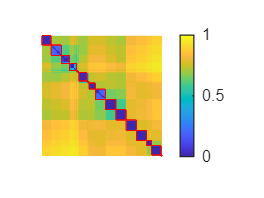

tree = linkage(distm_syn_subset,'average');
leafOrder = optimalleaforder(tree,distm_syn_subset);
dist_thresh = 0.4;
[metallore_groupid,metallore_groupnum,changedleaforder_bygroups] = Cluster_byconnection(distm_syn_subset,dist_thresh,leafOrder);
distm_syn_subset_reorder = distm_syn_subset(changedleaforder_bygroups,changedleaforder_bygroups);
sidero_product_reordered = sidero_product_subset(changedleaforder_bygroups);
sidero_info_91_reordered = sidero_info_91(changedleaforder_bygroups,:);
metallore_groupid = metallore_groupid(changedleaforder_bygroups);
plot_cluster(distm_syn_subset_reorder,metallore_groupid,'../Figure/syn_PBP2_heatmap.pdf')

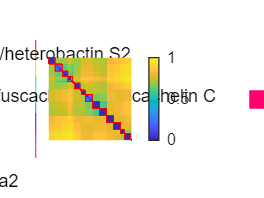

plot_cluster_colorbar(distm_syn_subset_reorder,metallore_groupid,sidero_product_reordered,'../Figure/syn_PBP2_heatmap_product.pdf')

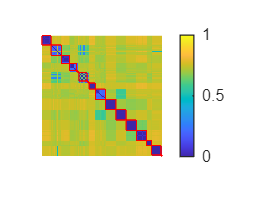

distm_rec_reorder = distm_rec(changedleaforder_bygroups,changedleaforder_bygroups);
plot_cluster(distm_rec_reorder,metallore_groupid,'../Figure/PBP2_heatmap.pdf')

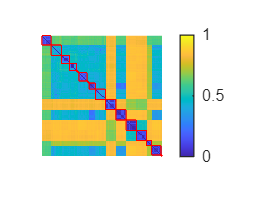

PBP2_id_reorder = PBP2_id(changedleaforder_bygroups);
Phylogeny_seqs = fastaread('../input/Total_fasta_concatenated.aln');
PBP2_id_strain_name = cellfun(@(x) extractBefore(x, '_N'), PBP2_id_reorder, 'UniformOutput', false);
Headers = {Phylogeny_seqs.Header};
[isMatch, idxInPhylogeny] = ismember(PBP2_id_strain_name, Headers);
%setdiff(PBP2_id_strain_name,matched_strain_name)
matched_strain_name = PBP2_id_strain_name(isMatch);
matched_seq = Phylogeny_seqs(idxInPhylogeny(isMatch));
seqs = {matched_seq.Sequence};
dist_matrix = seqpdist(seqs, 'Method', 'p-dist');  
dist_phylogeny= squareform(dist_matrix);  
%plot_cluster(dist_phylogeny,metallore_groupid)
plot_cluster(dist_phylogeny,metallore_groupid,'../Figure/phylogeny_PBP2_heatmap.pdf')

corr(distm_syn_subset_reorder(:),dist_phylogeny(:))

ans = 0.5816